# Prelab#5

**Ashkan Jafari**

**810197483**

[cons, Es_avg] = constellation(4, 'pam')

cons =    -1.3416
   -0.4472
    0.4472
    1.3416


Es_avg = 1

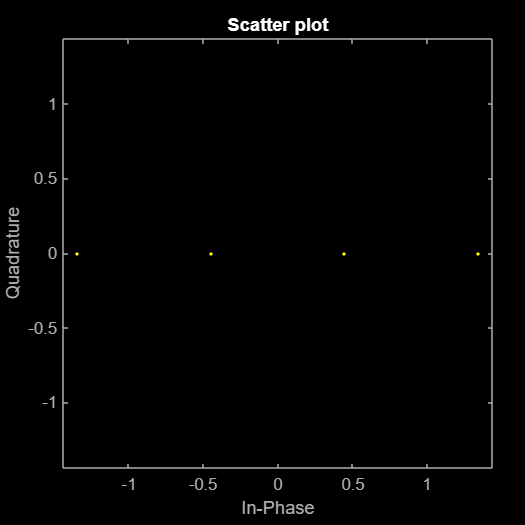

scatterplot(cons)

[cons, Es_avg] = constellation(16, 'psk')

cons =    1.0000 + 0.0000i
   0.9239 + 0.3827i
   0.7071 + 0.7071i
   0.3827 + 0.9239i
   0.0000 + 1.0000i
  -0.3827 + 0.9239i
  -0.7071 + 0.7071i
  -0.9239 + 0.3827i
  -1.0000 + 0.0000i
  -0.9239 - 0.3827i


Es_avg = 1

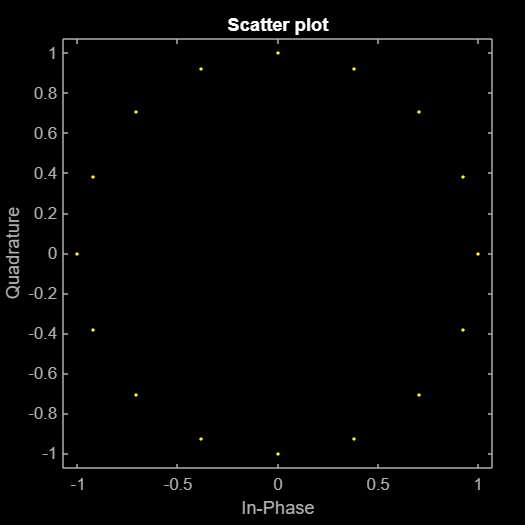

scatterplot(cons)

[cons, Es_avg] = constellation(32, 'qam')

cons =   -1.3728 - 0.5883i
  -1.3728 - 0.1961i
  -1.3728 + 0.1961i
  -1.3728 + 0.5883i
  -0.9806 - 0.5883i
  -0.9806 - 0.1961i
  -0.9806 + 0.1961i
  -0.9806 + 0.5883i
  -0.5883 - 0.5883i
  -0.5883 - 0.1961i


Es_avg = 1.0000

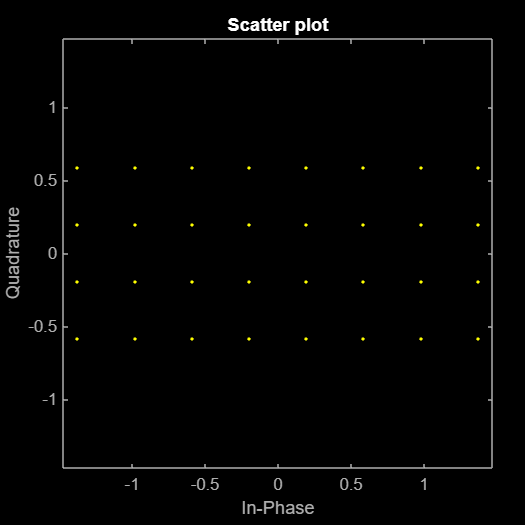

scatterplot(cons)

[cons, Es_avg] = constellation(4, 'psk')

cons =    1.0000 + 0.0000i
   0.0000 + 1.0000i
  -1.0000 + 0.0000i
  -0.0000 - 1.0000i


Es_avg = 1

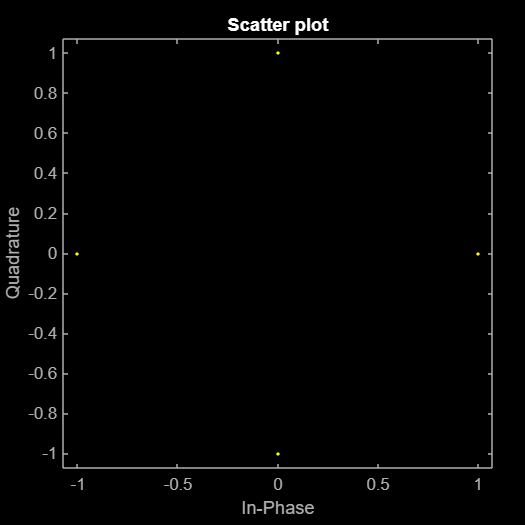

scatterplot(cons)

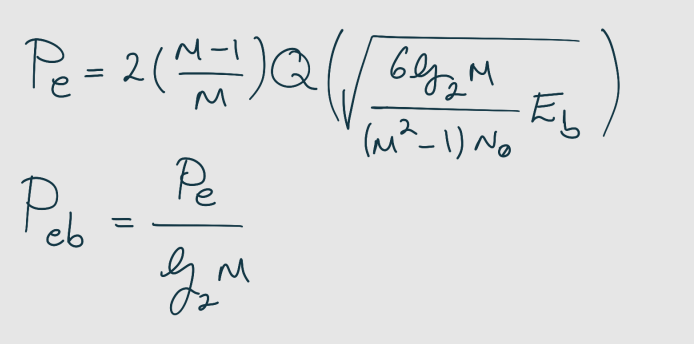

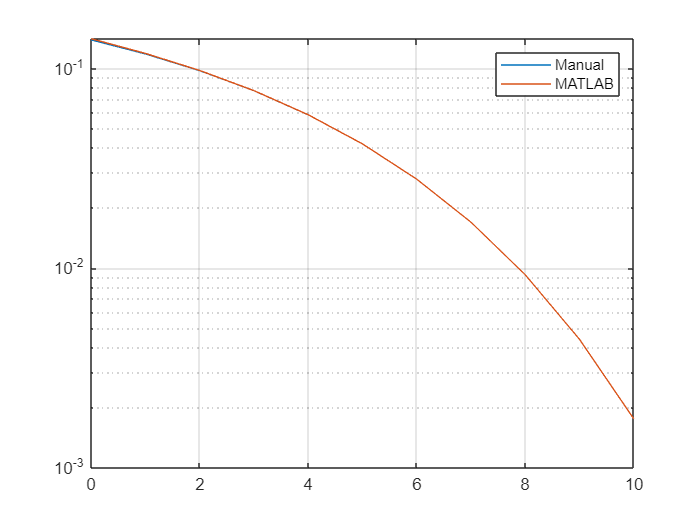

figure
M = 4;
EbNo_dB = (0:10)';
EbNo = db2pow(EbNo_dB);
BR_PAM = ((2 * (M - 1) / M) * qfunc(sqrt((6 * log2(M) * EbNo)/(M^2 - 1)))) / (log2(M));
[BR_PAM_matlab,~] = berawgn(EbNo_dB,'pam',4);
semilogy(EbNo_dB,[BR_PAM, BR_PAM_matlab])
legend('Manual','MATLAB')
grid on

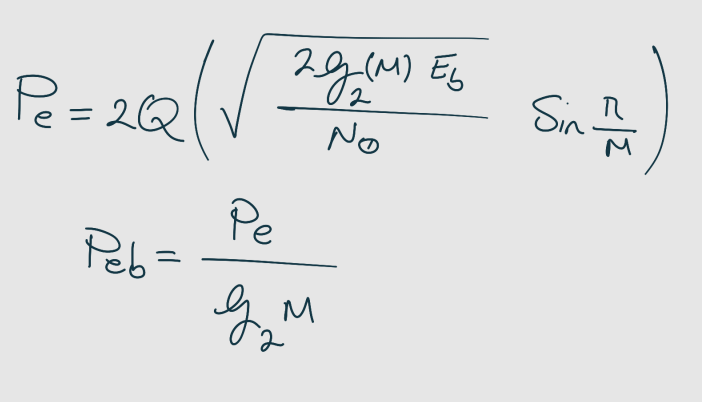

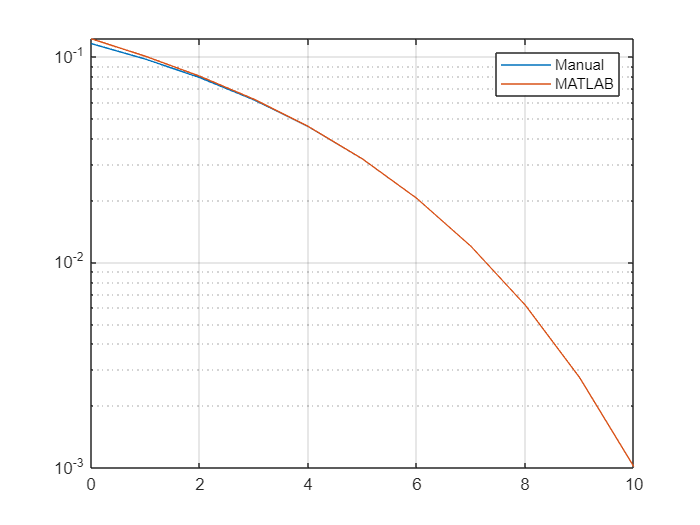

figure
M = 8;
EbNo_dB = (0:10)';
EbNo = db2pow(EbNo_dB);

BR_PSK =  (2 *  qfunc(sqrt((2 * log2(M) * EbNo)) * sin(pi/M)) / (log2(M)));
[BR_PSK_matlab, ~] = berawgn(EbNo_dB,'psk',8,'nondiff');
semilogy(EbNo_dB,[BR_PSK, BR_PSK_matlab])
legend('Manual','MATLAB')
grid on

figure
M = 16;
EbNo_dB = (0:10)';
EbNo = db2pow(EbNo_dB);
BR_QAM = (sqrt(M) - 1) / sqrt(M) *4 * ...
                qfunc(sqrt((3 * log2(M) * EbNo / (M - 1)))) / (log2(M));

[BR_QAM_matlab, ~] = berawgn(EbNo_dB,'qam',16);
semilogy(EbNo_dB,[BR_QAM, BR_QAM_matlab])
legend('Manual','MATLAB')
grid on

Functions.

function [cons, Es_avg] = constellation(M, modulation)
switch modulation
    case 'psk'
        m = (1:M).';
        tetha = 2 * pi * (m - 1) / M;
        cons = cos(tetha) + 1j * sin(tetha);
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
    case 'pam'
        m = (1:M).';
        cons = 2 * m - 1 - M;
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
    case 'qam'
        if mod(log2(M),2) == 0
            m = (-sqrt(M) + 1 : 2 : sqrt(M) - 1).';
            cons_old = m + (1j * m).';
            cons = cons_old;
            for i =1:1:sqrt(M)
                if(mod(i,2) == 0)
                    cons(:,i) = flip(cons_old(:,i));
                else
                    cons(:,i) = (cons_old(:,i));
                end
            end
            cons = cons(:);
        else
            m1 = floor(log2(M) / 2);
            m2 = log2(M) - m1;
            cons = (-2 ^ m2 + 1 : 2 : 2 ^ m2 - 1) + ... 
                                (1j * (-2 ^ m1 + 1 : 2 : 2 ^ m1 - 1)).';
            cons = cons(:);
        end
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
end
end